PHYSICS 434 - APPLICATION OF COMPUTERS TO PHYSICAL MEASUREMENT 

LAB 3 - ASKING STATISTICAL QUESTIONS 

AVI SOVAL 

DUE: 10.27.19

In this lab, we once again analyze the fundamentals of interpreting a signal-free background data distribution and determining the associated probabilities and sigmas of any sample measurements observed in it. We take extra care in accurately transcribing a statistical question into its mathematical equivalent, and then performing any necessary mathematical operations. 

PROBLEM 1 

We begin by looking at the temperature readings associated with an experiment. For the experiment to function requires a temperature of approximately 12 K with a standard deviation of 0.4 K. We simulate 100,000 random data points following this Gaussian distribution, and then add some anomalous data values as well. Our goal will be to establish some statistical metric that we can apply to the entire dataset - only the 'good' data should be able to pass this test while the 'bad' values are caught and omitted. 

Temp = random('Normal',12,0.4,[1,100000]);
badDATA = [10. 10.3 2.1 0 0 15.6 22.3 12.7];

goodTEMP = Temp; 
Temp = [Temp badDATA];

Let us first show the total 'Temp' dataset on a regular and logarithmic axis: 

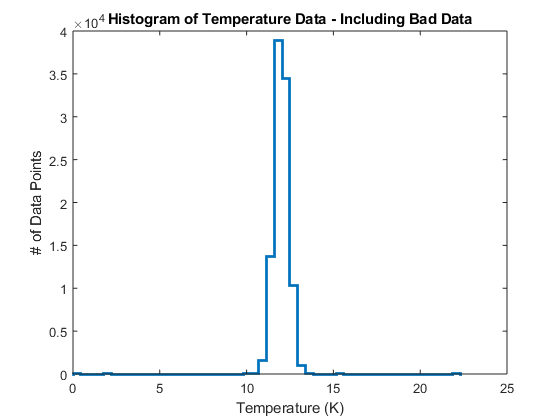

figure(1)
histogram(Temp,50,'DisplayStyle','stairs','Linewidth',2);
xlim([0,25]);
xlabel('Temperature (K)');
ylabel('# of Data Points');
title('Histogram of Temperature Data - Including Bad Data');

Note that the above plot has low resolution in its bin sizes because we have artificially extended the x-limits of the histogram to include the anomalous data. Reducing the x-range will improve the resolution greatly, at the cost of no longer being able to see the outliers and bad data in the dataset. Going forth, we narrow in on the range surrounding the mean and omit these outliers graphically; however, the entire dataset, bad data included, will still be subject to whatever statistical test we operate on it. 

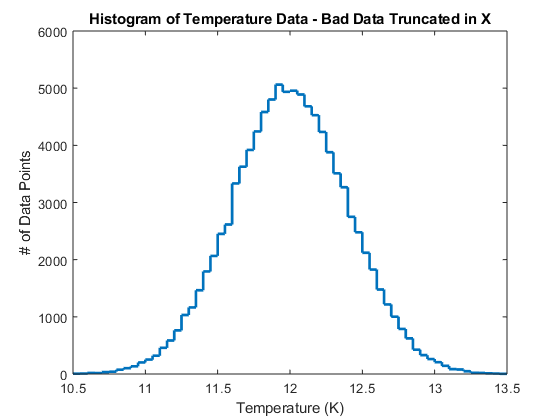

figure(2)
histogram(Temp,'BinWidth',.05,'DisplayStyle','stairs','LineWidth',2);
xlim([10.5,13.5]);
xlabel('Temperature (K)'); 
ylabel('# of Data Points'); 
title('Histogram of Temperature Data - Bad Data Truncated in X'); 

We plot this histogram on a logarithmic scale to analyze its Gaussian nature, and overlay a Gaussian probability density function with the same parameters to confirm the Gaussian nature of the temperature dataset. 

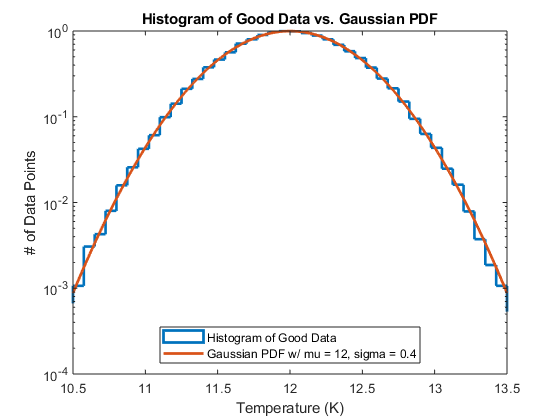

figure(3)
histogram(Temp,'BinWidth',0.075,'DisplayStyle','stairs','LineWidth',2,'Normalization','pdf'); 
xlim([10.5,13.5]); 
xlabel('Temperature (K)'); 
ylabel('# of Data Points'); 
title('Histogram of Good Data vs. Gaussian PDF'); 
hold on 
x = linspace(10.5,13.5,100000); 
gaussTEST = makedist('Normal','mu',12,'sigma',0.4); 
plot(x,pdf(gaussTEST,x),'LineWidth',2'); 
xlim([10.5,13.5]); 
set(gca,'YScale','log'); 
legend('Histogram of Good Data','Gaussian PDF w/ mu = 12, sigma = 0.4','location','south'); 

As expected, the histogram of the temperature dataset on a logarithmic scale looks like a parabola, and is almost perfectly overlayed by the Gaussian pdf made with the same parameters. 

Now, we wish to be able to define a statistical test capable of operating over the entire dataset and omitting our predefined 'bad' data. Thus, we seek to answer the following question: 

*Imagine we are given a large, Gaussian dataset. We then apply our metric to determine if a particular datapoint should be omitted or kept (without knowledge of whether that data point is actually good or not). If the metric we define is a sigma threshold above which a data point is considered unsuitable, how does the total number of correctly kept good data points and total number of correctly omitted bad data points change as we vary our sigma threshold - i.e our statistical metric?*

We answer this question in the code below using this methodology: 

 After creating a list of sigma-thresholds to compare against, we find the probability distribution to the right of each given sigma value. Then for each data point in the bad or good temperature dataset, we measure the corresponding probability against the threshold probability. Datapoints with probabilities less than the threshold are omitted, as this means that they would have fallen outside the sigma-bound and therefore do not pass our metric. Data values with probabilities greater than the threshold would have fallen inside the bounds and are therefore kept. 

% creating equally spaced sigmas of 0.5 on either side of the mean of 12
% and calculating the associated probability (area under the integral) of
% each
sigma_count = linspace(3,8,10); 
std = 0.4; 
xPos = 12 + sigma_count*0.4; 
xNeg = 12 - sigma_count*0.4; 

%splitting into values above and below the mean 
prob_xPos = zeros(1,length(xPos)); 
prob_xNeg = zeros(1,length(xNeg)); 

%actually finding the probabilities for each of the sigma threshold values
for a = 1:length(prob_xPos)
    
    prob_xPos(a) = normcdf(xPos(a),12,0.4,'upper'); 
    
end

for b = 1:length(prob_xNeg)
    
    prob_xNeg(b) = normcdf(xNeg(b),12,0.4); 
    
end

%initializing empty arrays that will sort the 'good' temperature data based
%on it being above or below the given mean 
tempLOW = []; 
tempHIGH = []; 

%sorting based on above condition 
for i = 1:length(goodTEMP)

    if goodTEMP(i) < 12
        tempLOW = [tempLOW goodTEMP(i)]; 
    end
    
    if goodTEMP(i) >= 12
        tempHIGH = [tempHIGH goodTEMP(i)];
    end
    
end

%doing the same thing as for the sigma threshold values, creating a
%probability (area integral to the right for both HIGH and LOW temp values)
%for each 'good' temperature value
tempHIGHprob = zeros(1,length(tempHIGH)); 
tempLOWprob = zeros(1,length(tempLOW));

for j = 1:length(tempHIGH)
       
    tempHIGHprob(j) = normcdf(tempHIGH(j),12,0.4,'upper'); 
    
end

for k = 1:length(tempLOW)
    
    tempLOWprob(k) = normcdf(tempLOW(k),12,0.4); 
    
end

badDATAlow = [10 10.3 2.1 0 0]; % bad data above and below the mean of the data set 
badDATAhigh = [15.6 22.3 12.7]; 

prob_badDATAlow = zeros(1,length(badDATAlow)); 
prob_badDATAhigh = zeros(1,length(badDATAhigh)); 

%creating probabilities for each of the 'bad' data points 
for i = 1:length(prob_badDATAhigh)
    
    prob_badDATAhigh(i) = normcdf(badDATAhigh(i),12,0.4,'upper'); 
    
end

for j = 1:length(prob_badDATAlow)
    
    prob_badDATAlow(j) = normcdf(badDATAlow(j),12,0.4); 
    
end

%counter for the true/false test table for the sigma threshold 
badKEEP = zeros(1,10); 
badOMIT = zeros(1,10); 
goodKEEP = zeros(1,10); 
goodOMIT = zeros(1,10); 

%this loop populates each of the threshold counters based whether the
%temperature or bad data reading is higher or lower than the probability
%associated with each sigma value
for i = 1:10
    
    %high temperature probabilites ('good data') 
    for j = 1:length(tempHIGHprob)
        if tempHIGHprob(j) <= prob_xPos(i)
            goodOMIT(i) = goodOMIT(i) + 1; 
        else
            goodKEEP(i) = goodKEEP(i) + 1;
        end
    end
    
    %low temperature probabilites ('good data')
    for k = 1:length(tempLOWprob)
        if tempLOWprob(k) <= prob_xNeg(i)
            goodOMIT(i) = goodOMIT(i) + 1; 
        else 
            goodKEEP(i) = goodKEEP(i) + 1;
        end
    end
    
    %bad temperature HIGH probabilities
    for j = 1:length(prob_badDATAhigh)
        if prob_badDATAhigh(j) >= prob_xPos(i)
            badOMIT(i) = badOMIT(i) + 1; 
        else
            badKEEP(i) = badKEEP(i) + 1; 
        end
    end
    
    %bad temperature LOW probabilites
    for l = 1:length(prob_badDATAlow)
        if prob_badDATAlow(l) <= prob_xNeg(i)
            badOMIT(i) = badOMIT(i) + 1; 
        else
            badKEEP(i) = badKEEP(i) +1;
        end
    end
    
end

testMATRIX = [goodKEEP;goodOMIT;badKEEP;badOMIT]; 
testTABLE = array2table(testMATRIX,'RowNames',{'Good Data Kept','Good Data Omitted','Bad Data Kept','Bad Data Omitted'});
disp(testMATRIX); 

       99747       99963       99995      100000      100000      100000      100000      100000      100000      100000
         253          37           5           0           0           0           0           0           0           0
           2           2           2           3           4           4           4           4           4           4
           6           6           6           5           4           4           4           4           4           4



We now plot the variation of good data kept and omitted vs. the sigma threshold, and do the same for the bad data. For ease, we normalize the y-axis by the total number of data points in the set to show how the *percentage *of total good and bad data is either kept or emitted. 

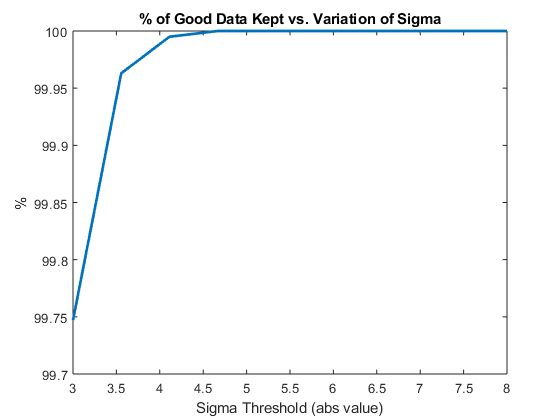

threshold = linspace(3,8,10); 
goodKEEPnorm = 100 * goodKEEP / length(goodTEMP); 
goodOMITnorm = 100 * goodOMIT / length(goodTEMP); 
badKEEPnorm = 100 * badKEEP / length(badDATA); 
badOMITnorm = 100 * badOMIT / length(badDATA); 

figure(4)
plot(threshold,goodKEEPnorm,'LineWidth',2); 
xlabel('Sigma Threshold (abs value)'); 
ylabel('%'); 
title('% of Good Data Kept vs. Variation of Sigma'); 

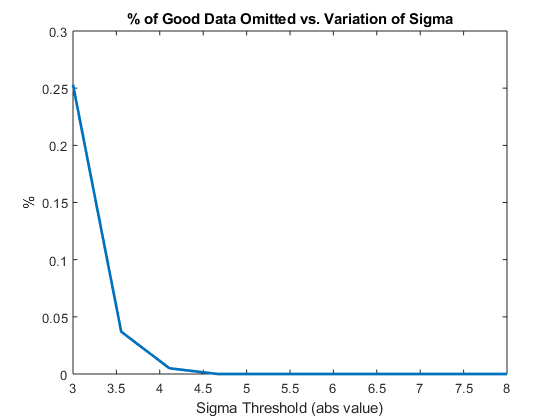


figure(5)
plot(threshold,goodOMITnorm,'LineWidth',2); 
xlabel('Sigma Threshold (abs value)'); 
ylabel('%'); 
title('% of Good Data Omitted vs. Variation of Sigma'); 

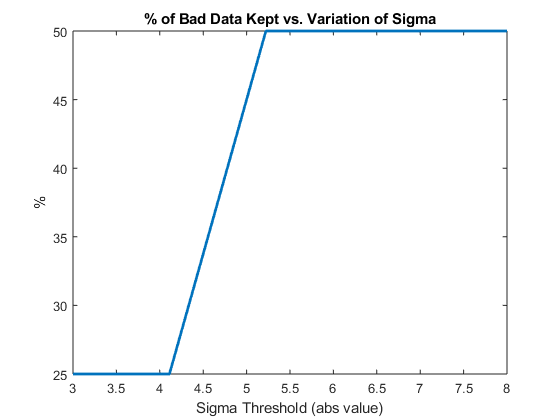


figure(6)
plot(threshold,badKEEPnorm,'LineWidth',2); 
xlabel('Sigma Threshold (abs value)'); 
ylabel('%'); 
title('% of Bad Data Kept vs. Variation of Sigma'); 

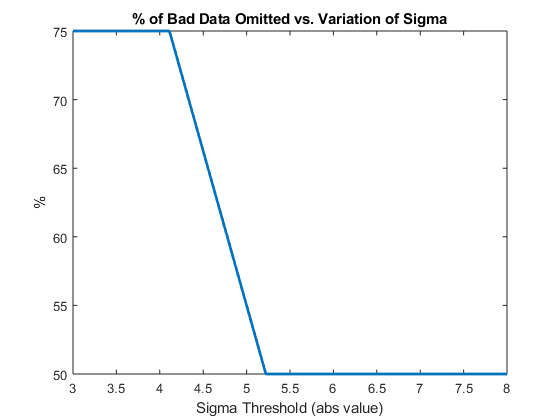


figure(7)
plot(threshold,badOMITnorm,'LineWidth',2); 
xlabel('Sigma Threshold (abs value)'); 
ylabel('%'); 
title('% of Bad Data Omitted vs. Variation of Sigma'); 

The above plots and table describe the variation in kept and omitted good and bad data as the sigma threshold increases. We find that as this threshold increases, the amount of good data kept increases while the amount of good data omitted decreases. This makes intuitive sense - increasing the sigma-threshold technically increases the maximum x-value (temperature reading) that would pass as viable data. Thus, good data points (even if they were distributed further from the mean) have a higher chance of passing the test, and being kept. Naturally, an increase in good data being kept causes a decrease in good data being erroneously omitted. 

However, the same trend is also seen for the bad data. Given that a portion of the bad data does fall inside the Gaussian that describes our dataset, increasing the threshold also increases the chance that this bad data makes it through our filter. This is a mistake of commission. Thus, we see a similar, but not proportional, rise in bad data kept with increasing sigma, and the corollary decrease in bad data omitted with increasing sigma. The bad data kept and omitted does experience a plateau, and this is due to the fact that some bad data were such large outliers that they still fall outside our maximum sigma threshold. Increasing the range of sigmas tested in our filter would cause the plateau to occur later or disappear entirely. 

PROBLEM II 

In this problem, we are given a 2D Gaussian distribution with an RMS of 1 arcsecond that describes the positional uncertainty of stars in subsequent (thus only two) images. Say we are trying to track an asteroid against this background data distribution, and that this asteroid will experience true movement likely beyond the average positional uncertainty experienced by the stars. We wish to qualitatively describe how to find a '5 sigma' detection of movement, and to translate that detection measurement into a distance given in arcseconds. 

To understand this problem, first consider the Gaussian along only 1 axis. If we look at the x-axis, then the positional uncertainty in the x-component of each star's location is on average 1 arcsecond and follows a Gaussian distribution. By integrating the area under this 1-dimensional Gaussian at different sigma values, we can determine the probabilities corresponding to the entire range of x-component uncertainties. The same can then be done along the y-axis, which means that we can calculate the probability outside a point on the 2D surface given by two positional uncertainties, delta x and delta y. 

This means that the problem we wish to solve for a 5 sigma detection becomes a simple extrapolation of all the 1-dimensional cases analyzed so far. A 5 sigma detection amounts to a probability of roughly 1 in 3.5 million, so the statistical question becomes: 

*At what point (delta x, delta y) does the volume of the region underneath the 2-D Gaussian and outside the given point equal 1 in 3.5 million? Any (x,y) location outside this threshold will then have a probability less than the threshold, which means that it has succesfully passed the threshold for a 5-sigma detection. *

If the 2D Gaussian of positional uncertainty can be described by a function $\rho =\rho \left(\Delta x,\Delta y\right)$, then the volume outside this region becomes: $\int_{\Delta y}^{\infty } \int_{\Delta x}^{\infty } \rho \left(\Delta x,\Delta y\right)d\Delta \mathrm{xd}\Delta y$. Assuming that the integral and Gaussian have been properly normalized, then the written question above can be expressed as the following mathematical inequality: 


$${\left(\Delta x,\Delta y\right)}_{5\sigma } \;|\;$$

$$\int_{\Delta y}^{\infty } \int_{\Delta x}^{\infty } \rho \left(\Delta x,\Delta y\right)d\Delta \mathrm{xd}\Delta y\le \frac{1}{3\ldotp 5*{10}^6 }$$
 

Where a pair of points $\left(\Delta x,\Delta y\right)$ pass the detection limit and become ${\left(\Delta x,\Delta y\right)}_{5\sigma }$ if the integral under those limits is less than the threshold probability for a 5-sigma detection.  

PROBLEM III 

In this problem we deal with detecting cosmic rays in the night sky. Since they come from all directions, it is logical to assume that the moon and the sun block a portion of the incoming rays, due to them physicaly obstructing their path in the night sky. Say that a moon-sized patch on the sky typically has a cosmic ray rate of 1 ray per minute. If we observe a moon-sized patch for 8 hours a day for 15 days and observe 6800 cosmic rays, what is the significance of our moon shadow detection? 

For this problem, our distribution is not Gaussian but instead Poisson, with a trials factor that relates the duration of the entire experiment to our 1-minute background data. This is because the detection of a cosmic ray is a discrete event that is independent of how far back in time the previous ray was detected. How can we restate the above question as a statistical question in words? 

As always, we are concerned with detecting the significance (sigma) of our measurement. That is, we seek to answer the question: 

*Over the duration of the experiment, what is the probability that the background data would have produced equal to or more than 6800 cosmic rays? *

If we can accurately construct a Poisson equation that describes our background data as well as incorporates the trials factor, then the statistical equation can be mathematically described as follows: 

$\mathit{Signifance}\;\left(%\right)=\int_{6800}^{\infty } P\left(x\right)\mathrm{dx}$ where P(x) is the given Poisson distribution. Converting the resultant probability to a sigma value is trivial. 

We now execute the above as follows:

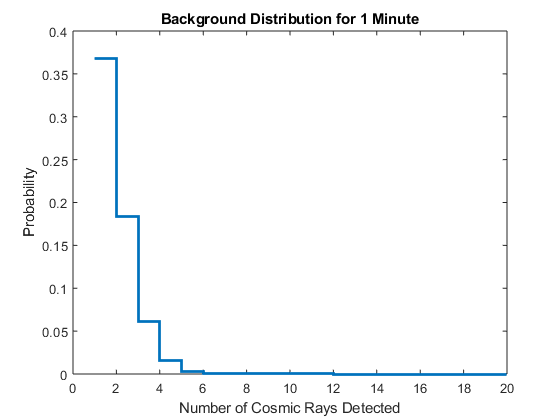

hours = 8; 
days = 15; 

minutes = 60*hours*days; 
trials = minutes; 

x = 1:20; 
background = 1; 
poisson = makedist('Poisson','lambda',background); 
fullPoisson = pdf(poisson,x) * minutes; 

figure(8)
stairs(x,pdf(poisson,x),'LineWidth',2); 
xlabel('Number of Cosmic Rays Detected'); 
ylabel('Probability'); 
title('Background Distribution for 1 Minute'); 

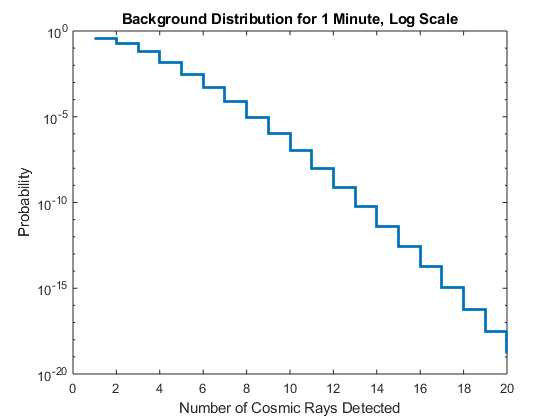


figure(9)
stairs(x,pdf(poisson,x),'LineWidth',2); 
xlabel('Number of Cosmic Rays Detected'); 
ylabel('Probability'); 
title('Background Distribution for 1 Minute, Log Scale');
set(gca,'YScale','log'); 

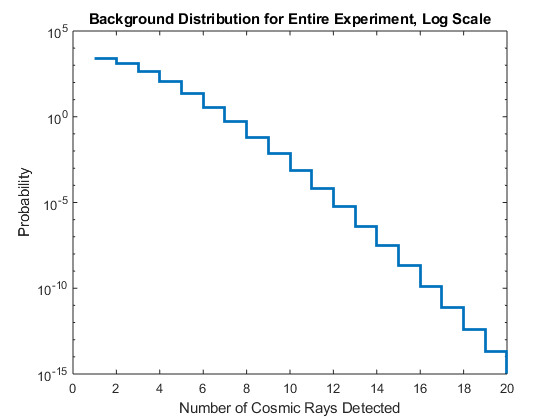


figure(11)
stairs(x,fullPoisson,'LineWidth',2); 
xlabel('Number of Cosmic Rays Detected'); 
ylabel('Probability'); 
title('Background Distribution for Entire Experiment, Log Scale');
set(gca,'YScale','log'); 


prob_1Min = cdf('Poisson',6800,1,'upper'); 
prob_Exp = prob_1Min * trials; 
sigma_Exp = norminv(prob_Exp); 

disp(abs(sigma_Exp)); 

   Inf



NOTE NOTE NOTE: HELP: I think I am running into a rounding error here. Finding the probability/significane for a count of 6800 rays against the background Poisson distribution for 1 minute gives an answer that is pretty much 0. Thus, multiplying this probability by the trials factor is still essentially 0 - and Matlab does indeed take this value to be 0. As a result, I cannot get a value for the sigma of this 6800 cosmic ray detection that is not infinity. Any thoughts/suggestions? 